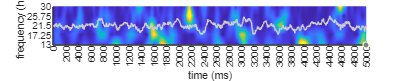

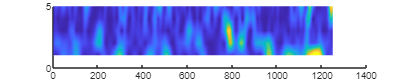

chan = [36]; n_chan = length(chan);

% find minimum period/peak separation for extrema finding
C.min_pd = 1000/P.band.range(2) * C.Fs/1000;

% iterate through epochs
n_epoch = max(cellfun(@(x) size(x,2),{X.data}));
for i_c = 1:n_chan
    % get channel events
    c = chan(i_c); CE = SE(c).events;%.Events;
    for i_ep = 1:n_epoch
        % get epoch filtered ts, extrema, event range
        epoch = get_epoch_info(X(c).data(:,i_ep),i_ep,CE,P,C,1); 
        % plot channel/epoch TFR
        figure('Position',[20 300 2000 400]), hold on
        pcolor(squeeze(TFR(c).tfr(:,:,i_ep))), shading interp, caxis([-0 5])
        plot(epoch.raw,'Color','#ccc')
        ylim([1 5]); xlabel('time (ms)'); ylabel('frequency (hz)')
        yticks(1:5); yticklabels(linspace(13,30,5));
        x_ts = round(linspace(C.t_win.to_keep(1),C.t_win.to_keep(2),length(epoch.raw)),-2);
        x_ts_i = [1:50:1250 1250];
        xlim([0 1250]); xticks(x_ts_i); xticklabels(x_ts(x_ts_i))
        % iterate through events
        for i_e = epoch.event_range
            % get event information
            [evt,tfr] = align_tfr_event_ts(CE(i_e),epoch,C.Fs,C.t_win,C.min_pd);
            % plot tfr event
            ymin = (CE(i_e).maximafreq-CE(i_e).Fspan/2-13)*4/17+1;
            xmin = tfr.win(1); x = tfr.win(2)-xmin; 
            rec_win = [xmin*C.Fs/1000 ymin x*C.Fs/1000 (CE(i_e).Fspan*4/17)];
            rectangle('Position',rec_win,'EdgeColor','#eee')
            % plot ts event
            xline(evt.ts_center_i_epoch,'--','Color',[1 0 0],'LineWidth',2)
            ts_x = evt.ts_onset_i_epoch:evt.ts_offset_i_epoch;
            plot(ts_x,epoch.raw(ts_x),'Color','#000','LineWidth',2)
        end
   end
end